# Module 3 Quiz & Practice App

## Analyzing concrete crack image data

The goal of this assessment is to analyze the concrete crack image data from the previous video. You will use the `crackData` table, which is provided in your course files in the file `CrackData.mat`.

In each concrete crack image, a single pixel has the dimensions of **0.5 mm **by** 0.5 mm**.

load CrackData.mat

% Define the cutoff area
cutoffArea = 4000;

% Discretize the data into categories based on the Area
crackData.Risk = discretize(crackData.Area, [0, cutoffArea, inf], ...
    "categorical", ["Mild", "Severe"]);

#### Quiz

Assume a single pixel in every image has the dimensions of 0.5 mm by 0.5 mm. What is the median MaxWidth of just the cracks labeled "Severe"? Provide your answer in millimeters.

% Filter the data for only the cracks labeled "Severe"
severeCracks = crackData(crackData.Risk == "Severe", :);

% Calculate the median of the MaxWidth for severe cracks in pixels
medianMaxWidthPixels = median(severeCracks.MaxWidth);

% Convert the median MaxWidth from pixels to millimeters
medianMaxWidthMillimeters = medianMaxWidthPixels * 0.5;

#### Practice App

- Convert the `MaxWidth` variable in the `cackData` table from number-of-pixels to millimeters.

- Convert the `Area` variable in the `cackData` table from number-of-pixels to squared millimeters.

- Calculate the mean `MaxWidth` in millimeters for all images with a `Risk` of `Mild`. Save this value in the variable `mildMeanWidth`.

- Calculate the mean `MaxWidth` in millimeters for all images with a `Risk` of `Severe`. Save this value in the variable `severeMeanWidth`.

pixelToMillimeter = 0.5;  % 1 pixel = 0.5 mm
pixelToSquareMillimeter = 0.5^2;

% Convert MaxWidth from pixels to millimeters
crackData.MaxWidth = crackData.MaxWidth * pixelToMillimeter;

% Convert Area from pixels to square millimeters
crackData.Area = crackData.Area * pixelToSquareMillimeter;

% Calculate the mean MaxWidth in millimeters for images with a Risk of Mild
mildMeanWidth = mean(crackData.MaxWidth(crackData.Risk == "Mild"));

% Calculate the mean MaxWidth in millimeters for images with a Risk of Severe
severeMeanWidth = mean(crackData.MaxWidth(crackData.Risk == "Severe"));

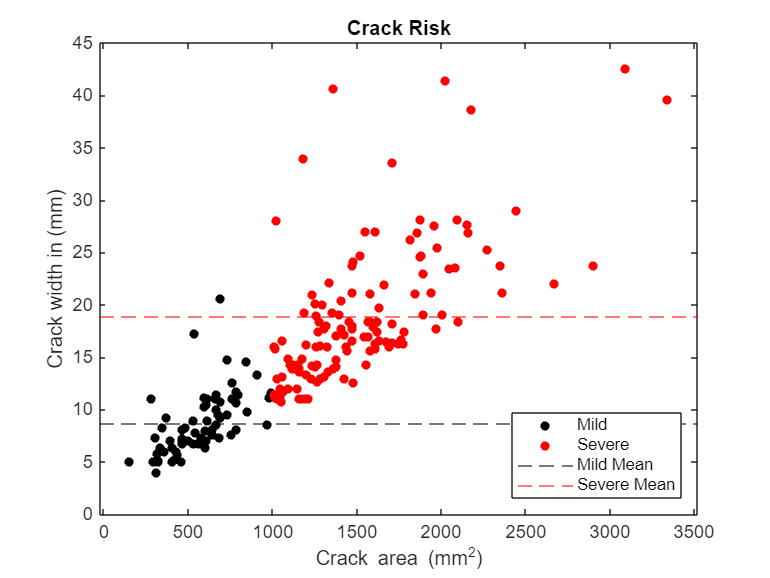

gscatter(crackData.Area,crackData.MaxWidth,crackData.Risk,"kr")
yline(mildMeanWidth,"k--","DisplayName","Mild Mean")
yline(severeMeanWidth,"r--","DisplayName","Severe Mean")
title("Crack Risk")
xlabel("Crack area (mm^2)")
ylabel("Crack width in (mm)")